行波驻波演示

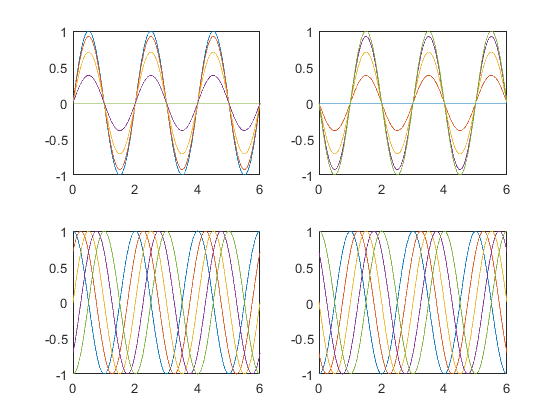

kz = pi;  % define kz
z = linspace(0,6,1000); % define range of z
T = 10; % cycle of wave
omega = 2*pi/T; % Angular frequency
t = (0:4)/4*T/4; % set 5 observation points
for lp=1:length(t)
    U(lp,:) = sin(kz*z)*cos(omega*t(lp)); 
end
subplot(2,2,1);
plot(z,U);
t = (4:8)/4*T/4;
for lp=1:length(t)
    U(lp,:) = sin(kz*z)*cos(omega*t(lp));
end
subplot(2,2,2);
plot(z,U);
t = (0:4)/4*T/2; % set 5 observation points
for lp=1:length(t)
    U(lp,:) = cos(omega*t(lp)-kz*z); 
end
subplot(2,2,3);
plot(z,U);
t = (4:8)/4*T/2; % set 5 observation points
for lp=1:length(t)
    U(lp,:) = cos(omega*t(lp)-kz*z); 
end
subplot(2,2,4);
plot(z,U);